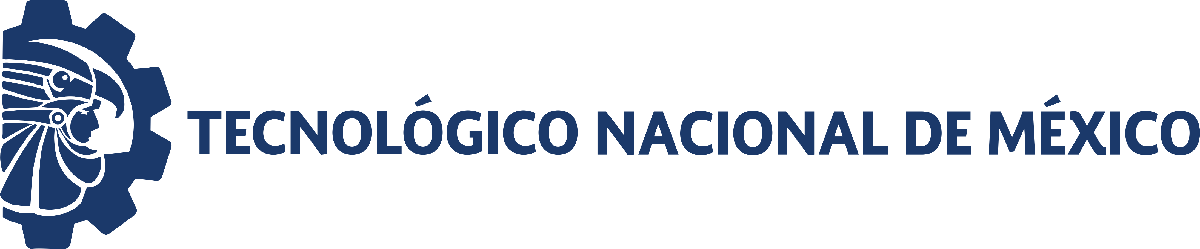                                 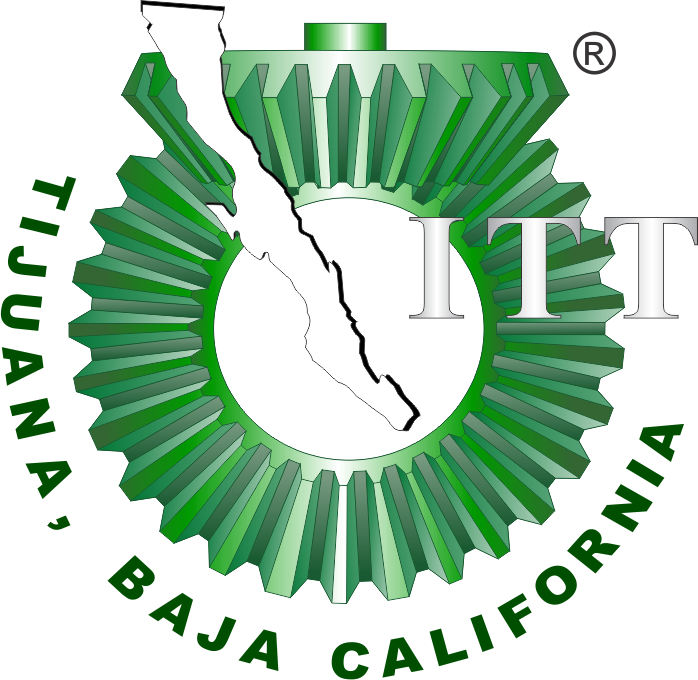

# Práctica 3: Sistema cardiovascular 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

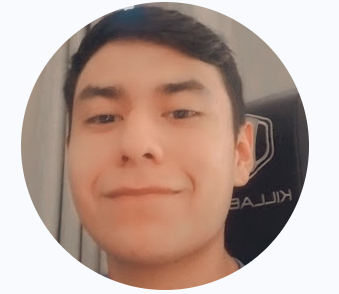

Nombre del alumno: Cesar Andres Ramirez Diaz

Número de control: 21212173

Correo institucional: l21212173**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

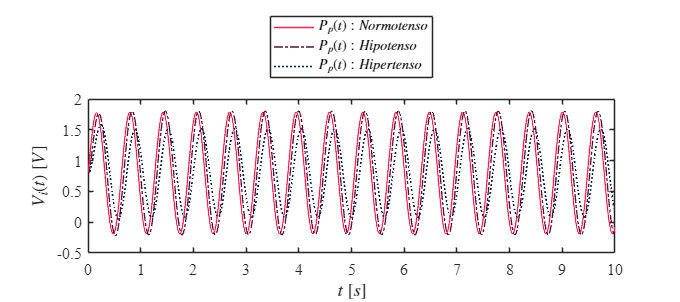

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sysp4';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim (file, parameters);
plotsignal1 (x.t, x.Ppx, x. Ppy, x.Ppz)

## Rendimiento del controlador

kI = 1034.73647017467 

Settling time = 0.00391 s

Overshoot = 0%

Peak = 0.999

## Hipotenso

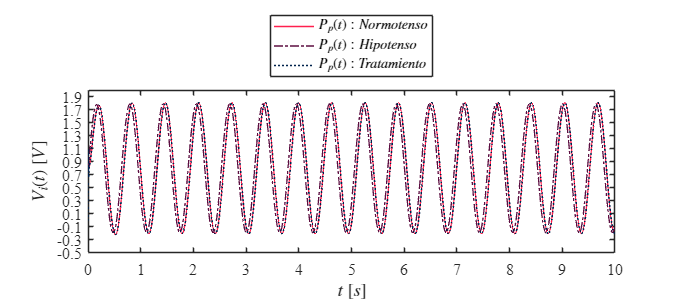

file = 'sysp4_Hipotenso';
open_system(file);
x = sim (file, parameters);
opt = 'Hipotenso';
plotsignal (x.t, x.Ppx, x. Ppy, x.Ppz, opt)

## Hipertenso

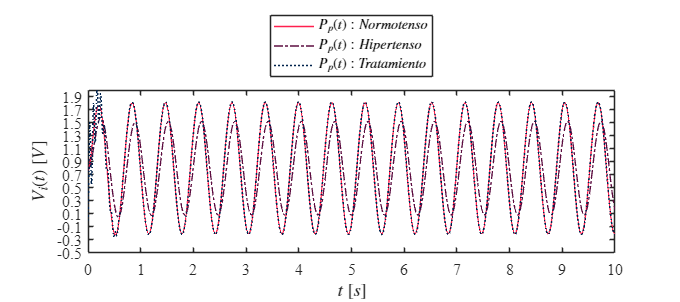

file = 'sysp4_Hipertenso';
open_system(file);
x = sim (file, parameters);
opt = 'Hipertenso';
plotsignal (x.t, x.Ppx, x. Ppy, x.Ppz, opt)

## Función

function plotsignal(t, Ppx, Ppy, Ppz, opt)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
rosa = [255/255, 32/255, 78/255];
morado = [93/255, 14/255, 65/255];
azul = [0/255, 34/255, 77/255];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Ppx, 'timeseries'), Ppx = Ppx.Data(:); end
if isa(Ppy, 'timeseries'), Ppy = Ppy.Data(:); end
if isa(Ppz, 'timeseries'), Ppz = Ppz.Data(:); end


plot(t, Ppx, 'LineWidth', 1,'Color',rosa)
plot(t, Ppy, '-.', 'LineWidth', 1,'Color', morado)
plot(t, Ppz,':', 'LineWidth', 1.2,'Color', azul)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
if opt == "Hipotenso"
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipotenso$', '$P_p(t): Tratamiento$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')

xlim([0, 10]); xticks(0:1:10)
ylim([-0.5, 2]); yticks(-0.5:0.2:2)
elseif opt == "Hipertenso"
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipertenso$', '$P_p(t): Tratamiento$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')
xlim([0, 10]); xticks(0:1:10)
ylim([-0.5, 2]); yticks(-0.5:0.2:2)
end

exportgraphics(gcf,[opt,'.pdf'], 'ContentType', 'Vector')
exportgraphics(gcf,[opt,'.png'], 'Resolution', 600);
print(opt, '-dsvg');
print(opt, '-depsc');
end

## Función dos

function plotsignal1(t, Ppx, Ppy, Ppz)
set(figure(), 'Color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
set(gca, 'FontName', 'Times New Roman')
fontsize(12, 'points')
rosa = [255/255, 32/255, 78/255];
morado = [93/255, 14/255, 65/255];
azul = [0/255, 34/255, 77/255];
hold on; grid off; box on

t = t(:);
% Convertir objetos timeseries a arreglos numéricos
if isa(Ppx, 'timeseries'), Ppx = Ppx.Data(:); end
if isa(Ppy, 'timeseries'), Ppy = Ppy.Data(:); end
if isa(Ppz, 'timeseries'), Ppz = Ppz.Data(:); end


plot(t, Ppx, 'LineWidth', 1,'Color',rosa)
plot(t, Ppy, '-.', 'LineWidth', 1,'Color', morado)
plot(t, Ppz,':', 'LineWidth', 1.2,'Color', azul)
xlabel('$t$ $[s]$', 'Interpreter','Latex')
ylabel('$V_i (t)$ $[V]$', 'Interpreter','Latex')
L = legend('$P_p(t): Normotenso$', '$P_p(t): Hipotenso$', '$P_p(t): Hipertenso$');
set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')
end